# Padé approximation of natural logarithms

This file contains the code to approximate the natural logarithm ($\ln x$) using Padé approximation. The `pade` function provides approximation for many functions.

**Preparation**: Clear everything and set formatting.

clc
format loose

syms x
f = log(x) % f is the natural logarithm of x

$$f = \log\left(x\right)$$

**Approximation**: Try to find the best approximant of the natural logarithm.

*Note*:

- Drag the slider to adjust the center of the Padé approximant.

- 1 seems to produce a clear and simple output.

a =1

a = 1


% 1 is the best for now...
% error: 0.0105

g = pade(f, x, a, 'Order', [5 5])

$$g = \frac{\left(x-1\right)\,\left(137\,x^{4}+1762\,x^{3}+3762\,x^{2}+1762\,x+137\right)}{30\,\left(x^{5}+25\,x^{4}+100\,x^{3}+100\,x^{2}+25\,x+1\right)}$$

e = abs(f - g)

$$e = \left|\log\left(x\right)-\frac{\left(x-1\right)\,\left(137\,x^{4}+1762\,x^{3}+3762\,x^{2}+1762\,x+137\right)}{30\,\left(x^{5}+25\,x^{4}+100\,x^{3}+100\,x^{2}+25\,x+1\right)}\right|$$

**Evaluation**: Find the errors of the approximation.

x_values = linspace(0, 1, 1e2)

x_values =          0    0.0101    0.0202    0.0303    0.0404    0.0505    0.0606    0.0707    0.0808    0.0909    0.1010    0.1111    0.1212    0.1313    0.1414    0.1515    0.1616    0.1717    0.1818    0.1919    0.2020    0.2121    0.2222    0.2323    0.2424    0.2525    0.2626    0.2727    0.2828    0.2929    0.3030    0.3131    0.3232    0.3333    0.3434    0.3535    0.3636    0.3737    0.3838    0.3939    0.4040    0.4141    0.4242    0.4343    0.4444    0.4545    0.4646    0.4747    0.4848    0.4949


err = double(subs(e, x, x_values))

err =        NaN    0.5403    0.2247    0.1128    0.0623    0.0366    0.0224    0.0142    0.0092    0.0061    0.0041    0.0028    0.0020    0.0014    0.0010    0.0007    0.0005    0.0004    0.0003    0.0002    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


mean(err, 'omitnan')

ans = 0.0105

**Visualization**: Graph the errors and see the covergence.

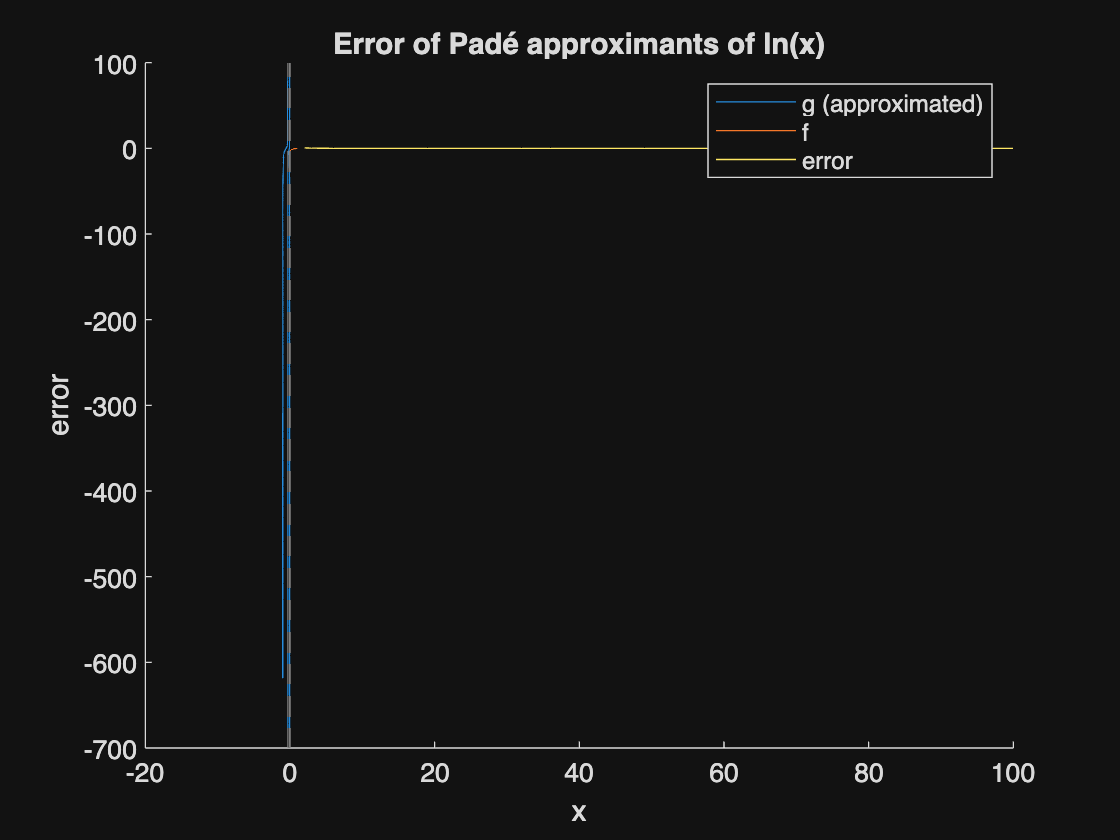

figure
hold off
hold on
fplot(g, [-1 1])
fplot(f, [-1 1])
plot(err)

title('Error of Padé approximants of ln(x)')
legend('g (approximated)', 'f', 'error')
xlabel('x')
ylabel('error')